% Generate a time domain signal
t = linspace(0, 1, 100); % Time values from 0 to 1 second
frequency = 20; % Frequency of the signal in Hz
amplitude = 1; % Amplitude of the signal
signal = amplitude * sin(2 * pi * frequency * t);

% Add noise to the signal
noise_amplitude = 0.2;
noisy_signal = signal + noise_amplitude * randn(size(signal));

% Perform FFT to convert the signal to the frequency domain
fft_result = fft(noisy_signal);

  Columns 1 through 6

   0.0812 + 0.0000i  -0.8664 + 0.0926i   0.2784 - 0.2096i   1.5828 - 0.3168i  -2.8166 + 0.6936i  -0.4783 - 0.9575i

  Columns 7 through 12

  -2.3717 - 1.3656i  -0.3336 + 2.4480i  -0.8256 - 0.1769i   1.0000 - 3.0816i   2.8995 - 1.8731i   3.3888 - 2.4107i

  Columns 13 through 18

  -1.9051 + 0.5121i   0.9245 - 0.4076i   2.3347 - 2.6789i   0.3156 - 2.4382i   2.0481 - 2.1982i  -1.0011 - 2.1143i

  Columns 19 through 24

   2.2303 - 2.1443i   3.1113 - 5.6740i  28.1856 -35.7289i  -6.5332 + 8.3868i  -4.1936 + 4.1389i  -5.4288 - 1.5567i

  Columns 25 through 30

  -3.9728 + 0.9187i  -1.5023 + 1.0436i   1.2640 + 0.1021i  -2.2489 + 2.0588i  -3.0164 - 1.1930i   0.1842 + 0.4929i

  Columns 31 through 36

   0.5477 - 0.0528i  -1.3848 + 1.2200i  -0.6175 + 1.7716i  -1.4974 + 3.6026i  -0.7710 - 0.2844i   1.1786 + 2.5928i

  Columns 37 through 42

   2.1977 - 0.7279i   0.7244 - 1.3374i  -1.9908 + 0.3274i   0.3421 - 1.1663i  -2.8529 + 0.2769i   1.5536 + 2.0786i

  Columns 43 thr

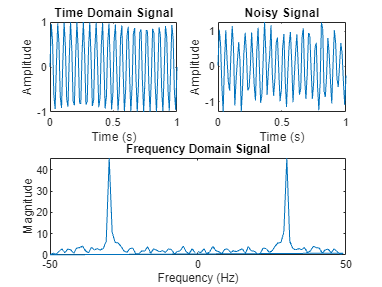


% Compute the corresponding frequency values
sampling_rate = length(t) / (t(end) - t(1)); % Calculate the sampling rate
frequencies = fftshift((-sampling_rate/2):(sampling_rate/length(t)):(sampling_rate/2)-(sampling_rate/length(t)));

% Plot the time domain signal
subplot(2, 2, 1);
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time Domain Signal');

% Plot the noisy signal
subplot(2, 2, 2);
plot(t, noisy_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Signal');

% Plot the frequency domain signal
subplot(2, 2, [3, 4]);
plot(frequencies, abs(fftshift(fft_result)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain Signal');


% Compute the dominant frequencies and their corresponding magnitudes
num_dom_freqs = 5; % Number of dominant frequencies to display
[sorted_magnitudes, sorted_indices] = sort(abs(fft_result), 'descend');
dominant_frequencies = frequencies(sorted_indices(1:num_dom_freqs));
dominant_magnitudes = sorted_magnitudes(1:num_dom_freqs);

% Display the dominant frequencies and their magnitudes
disp('Dominant Frequencies:');

Dominant Frequencies:


disp(dominant_frequencies);

    20   -20    21   -21    19



disp('Corresponding Magnitudes:');

Corresponding Magnitudes:


disp(dominant_magnitudes);

   45.5080   45.5080   10.6311   10.6311    6.4710




% Find the peak frequency
peak_frequency = frequencies(sorted_indices(1));
disp('Peak Frequency:');

Peak Frequency:


disp(peak_frequency);

    20



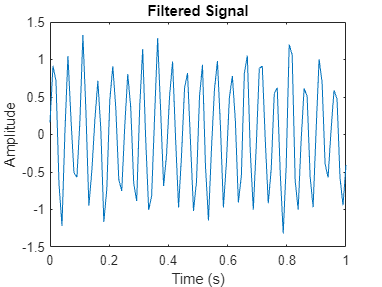


% Filter the noisy signal in the frequency domain
filtered_result = fft_result;
filtered_result(abs(frequencies) > 2*frequency) = 0; % Apply frequency domain filtering

% Perform inverse FFT to obtain the filtered signal in the time domain
filtered_signal = ifft(filtered_result);

% Plot the filtered signal in the time domain
figure;
plot(t, real(filtered_signal));
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal');